J=0.2

J = 0.2000

B=3

B = 3

K=250

K = 250

tau=0.001*50 % in second

tau = 0.0500

k_e=20

k_e = 20

b_e=1.2

b_e = 1.2000

m_e=0%% .1

m_e = 0

P_t=0

P_t = 0

I_t=1

I_t = 1

I_m=12

I_m = 12

P_m=20

P_m = 20

clear s; 
syms s;
x=s

$$x = s$$

[numa dena]=numden(eval(Z2));
numa=eval(fliplr(coeffs(numa,s)));
dena=eval(fliplr(coeffs(dena,s)));
sys=tf(numa,[dena 0]);
%Z=tf([1 20 100],[100 0])
w = logspace(-2,3,40)

w = 	1.0e+03 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0003    0.0003    0.0005    0.0006    0.0008    0.0011    0.0015    0.0020    0.0027    0.0037    0.0049    0.0066    0.0089    0.0119    0.0160    0.0215    0.0289    0.0389    0.0522    0.0702    0.0943    0.1266    0.1701    0.2285    0.3070    0.4125    0.5541    0.7444    1.0000


[re,im,freq] = nyquist(sys,w);
syms w
syms(w,'real');
s=j*w

$$s = w\,\mathrm{i}$$

%Z2=(s^2+20*s+100)/(100*s)
%Z2=eval(Z2)
im_pos_index=find(( im>0 ))

im_pos_index =     22
    23
    24
    25


im_neg_index=find(( im<0 ))

im_neg_index =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


re_pos_index=find(( re>0 ))

re_pos_index =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


ES=[]


ES =

     []



EM=[]


EM =

     []



ED=[]


ED =

     []



a=1

a = 1

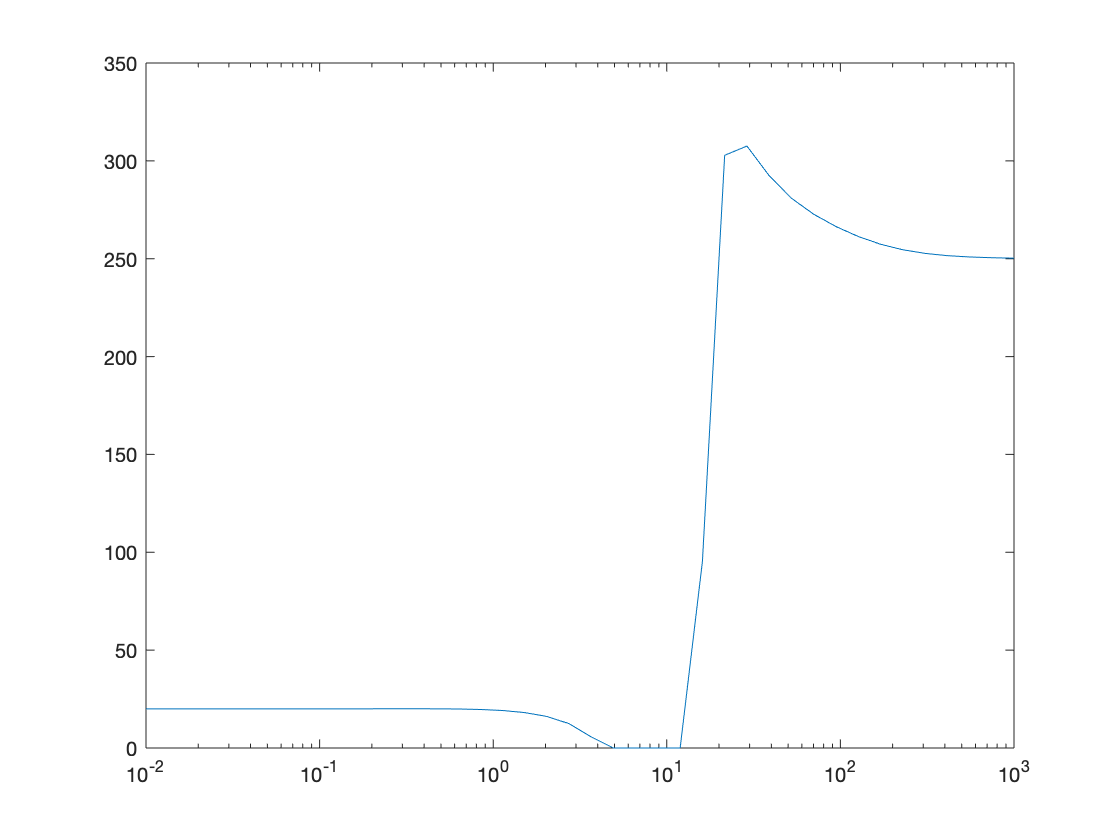

for i=1:length(freq)
    if any(im_neg_index==i)
    ES(i)=-freq(i)*im(:,:,i);
    else
    ES(i)=0;
    end
end
for i=1:length(freq)
    if any(im_pos_index==i)
    EM(i)=freq(i)^-1*im(:,:,i);
    else
    EM(i)=0;
    end
end
for i=1:length(freq)
    if any(re_pos_index==i)
    ED(i)=re(:,:,i);
    else
    ED(i)=0;
    end
end
plot(freq,ES)
set(gca, 'XScale', 'log')

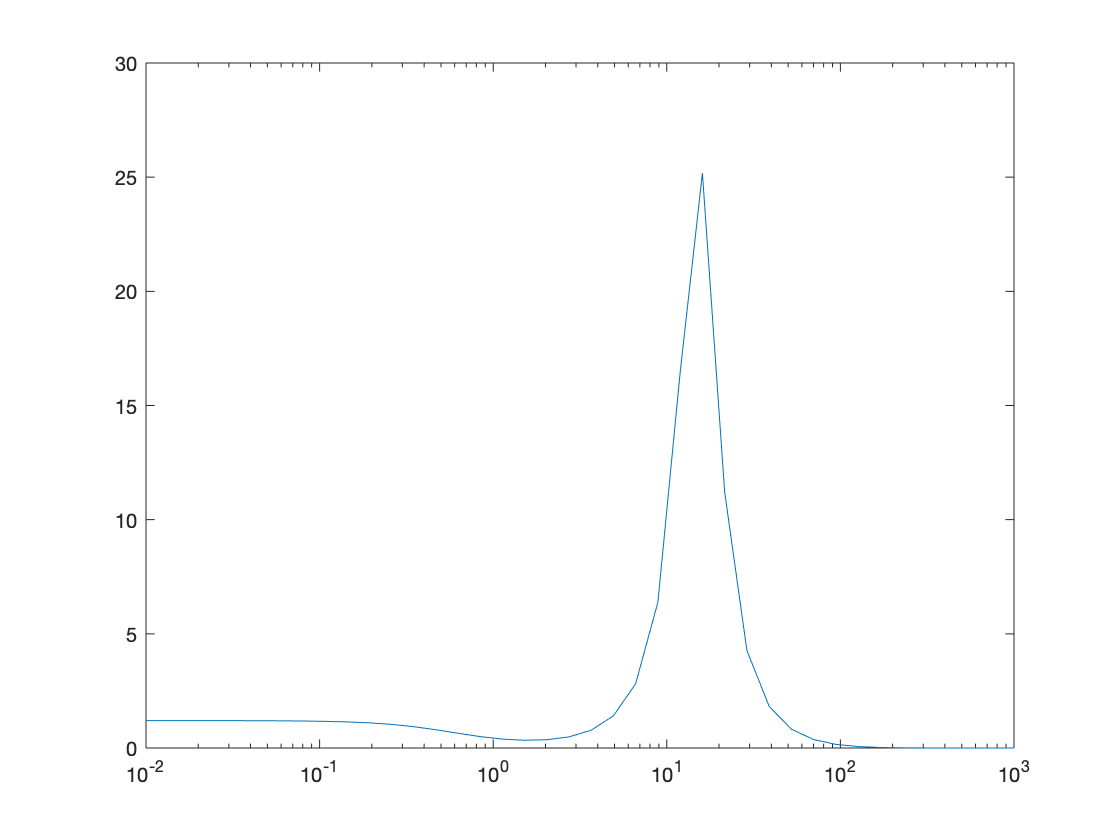

plot(freq,ED)
set(gca, 'XScale', 'log')

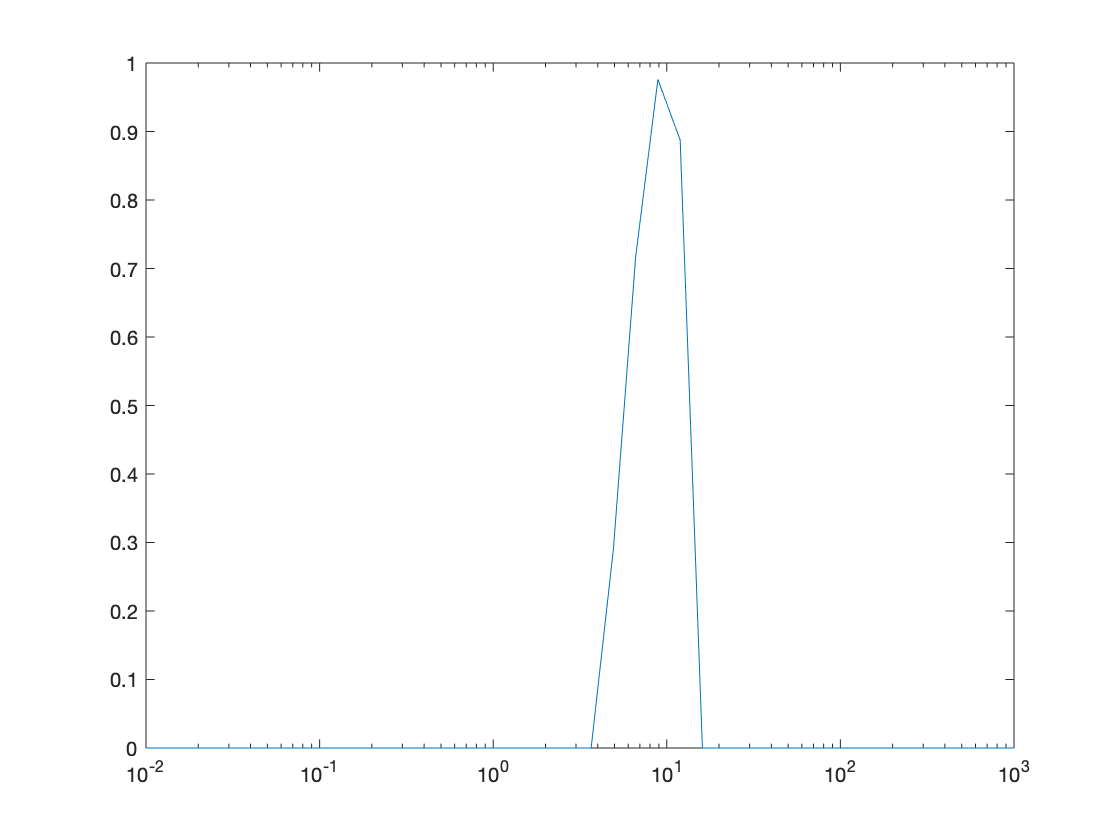

plot(freq,EM)
set(gca, 'XScale', 'log')

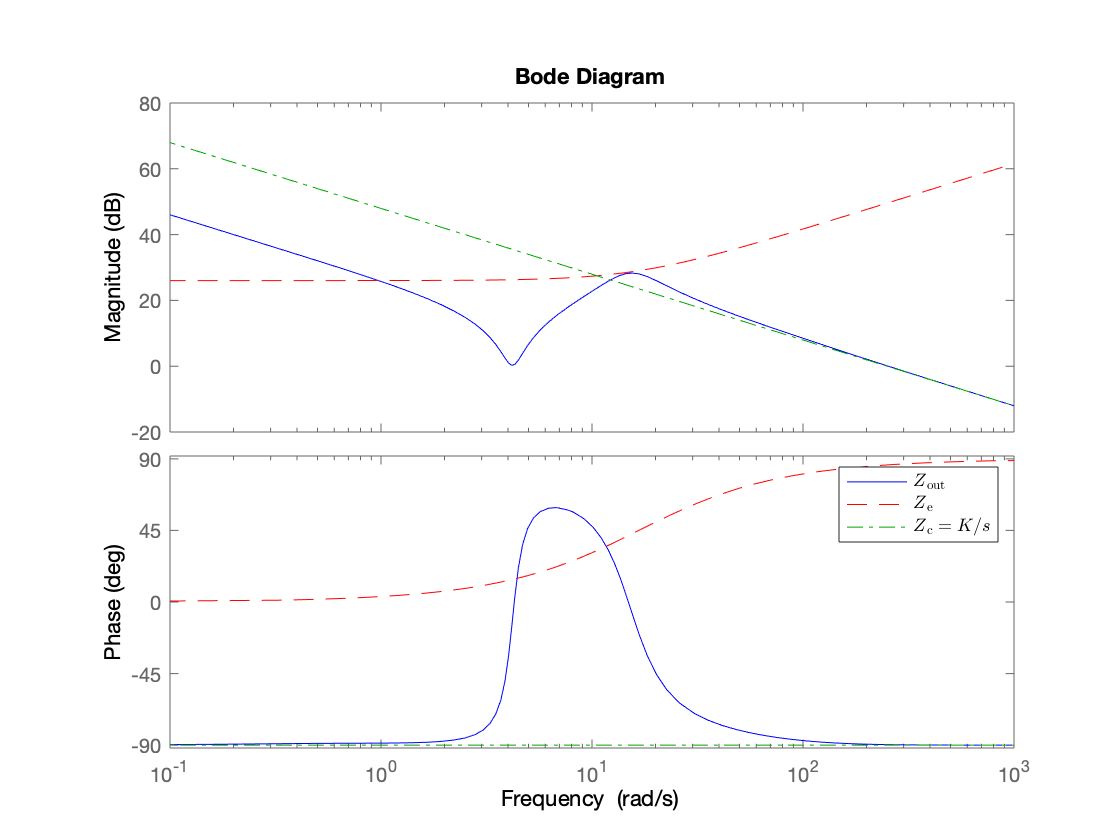

clear s; syms s
phy=tf([K],[1, 0]);
[nume dene]=numden((Z_d));
dene=eval(fliplr(coeffs(dene,s)));
nume=eval(fliplr(coeffs(nume,s)));
env=tf(nume,dene);

% Normal below
bode(sys,'b-',env,'r--',phy,'g-.') 
h = legend('$Z\_{\mathrm{out}}$', '$Z\_{\mathrm{e}}$', '$Z\_{\mathrm{c}}=K/s$'); set(h, 'Interpreter', 'latex');